**Bit error rate of Binary Phase Shift Keying (BPSK) in Additive White Gaussian Noise (AWGN)**

In this experiment, you will be generating data bits and modulating using BPSK modulation. Additive white Gaussian noise has to be added to the modulated bits. This is followed by demodulation. Obtain the error in the demodulated bits and plot Bit Error Rate (BER) vs. Signal to Noise Ratio (SNR) curves for simulated values. Compare this with the theoretical values obtained using the equation based on Q-function.

Step 1: Declare the number of binary data bits and generate them randomly.

z=10^6 ;
%%z=size of data 
b=randi(2,z,1) ;
%%binary data
disp('Binary data :') ;

Binary data :


bdata=b-1 

bdata =      0
     0
     0
     1
     0
     0
     1
     1
     1
     0


Step 2: Perform bit to symbol mapping - BPSK modulation

%%symbol sequence
sdata=zeros(size(bdata)) ;
for i=1:size(bdata)
    if bdata(i)==0 
        sdata(i)=-1 ;
    else
        sdata(i)=1 ;
    end
end
disp('Data sequence after mapping 0 to -1 and 1 to 1 :')

Data sequence after mapping 0 to -1 and 1 to 1 :


sdata

sdata =     -1
    -1
    -1
     1
    -1
    -1
     1
     1
     1
    -1


Step 3: Generate AWGN noise of a certain SNR value and add to the BPSK modulated bits

%%dBN=SNR value in dB.
s=10 ;%%Limit of SNR.
error=zeros(1,s) ;
for dBN=1:1:s
    var = 1/(10^(0.1*(dBN-1))) ;
    noise = sqrt(var/2).*randn(z,1) ;
    y= sdata+noise ;
    i=1:z ;
    scatter(y(i),randn(z,1))

Step 4: Demodulate using ML detection

    mest=zeros(size(y)) ; 
    for j=1:size(y) 
        if y(j) > 0
            mest(j)=1 ;
        else
            mest(j)=-1 ;
        end
    end

Step 5: Map the demodulated symbols to bits

    m=zeros(size(mest)) ;
    for k=1:size(m)
        if mest(k)==1
            m(k)=1 ;
        else 
            m(k)=0 ;
        end
    end

Step 6: Compare the demodulated bits with the data bits to obtain BER

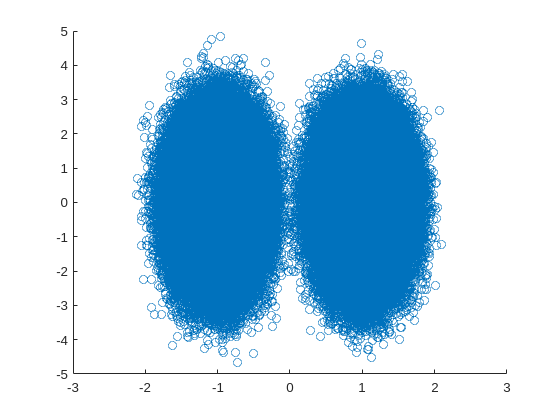

    for l=1:size(m)
        if m(l)~=bdata(l)
            error(dBN)=error(dBN)+1 ;
        else 
            error(dBN)=error(dBN)+0 ;
        end
    end
end

disp('An example of Noise added signal :') ;

An example of Noise added signal :


y

y =    -1.0023
   -1.2109
   -1.1527
    0.9201
   -1.2205
   -0.9836
    0.5074
    0.9562
    0.8325
   -0.9422


error

error =        78242       56789       37682       22826       12467        5940        2430         763         208          25


Step 7: Plot BER v/s SNR curve for a range of SNR values

BER=zeros(1,s) ;
for p=1:s
    BER(p)=error(p)/z ;
end
semilogy([0,1,2,3,4,5,6,7,8,9],BER) ;
hold on ; 
grid on
xlabel("SNR(in dB)")
ylabel("BER(log-scale)")

Step 8: Obtain the theoretical BER values through Q-function and compare with the simulated values

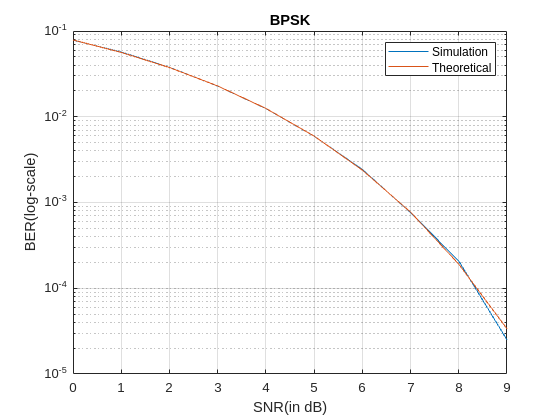

theoBER=zeros(size(BER)) ;
for m=1:s
    n0=10^(-0.1*(m-1)) ;
    theoBER(m)= qfunc(sqrt(2/n0)) ;
end
semilogy([0,1,2,3,4,5,6,7,8,9],theoBER) ;
hold off ;
legend(["Simulation","Theoretical"])
title("BPSK") ;

Observation and Inference:

- Comment on the BER v/s SNR curve

- How will the performance differ if MAP is used instead of ML?

- Will the performance differ if the mapping of bits to symbols change? That is if bit 0 is mapped to -1 and bit 1 is mapped to +1 and vice versa?

- Comment on the theoretical and simulated BER values.